# Inertia properties of a 3 blade propeller

## What we're going to do:

In this FAQ, we're going to explore the inertia properties of a 3 bladed propeller.  

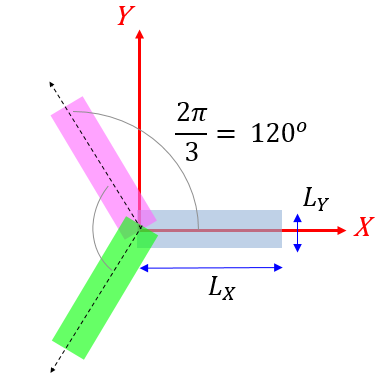

**WHY are we doing this?**

- We get to practice the calculation of Inertia matrices for "rotated" bodies, eg: parallel axis theorem and PASSIVE rotation matrices.

- The 3 bladed propeller has some inertia matrix properties that will blow your mind !!

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Consider a thin Rectangular plate:

Before we start looking at the 3 bladed propeller, let's quickly review the inertia matrix of a thin rectangular plate.  We're doing this because we'll represent a propeller blade as a thin rectangular plate.

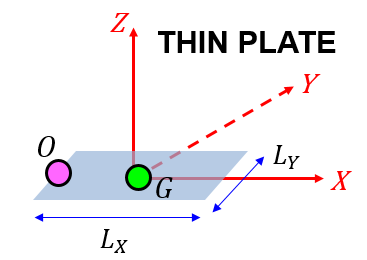  

In this figure we have a G-frame attached to the Centre of mass of the plate, Let's calculate the inertia of the plate about a parallel frame that is attached at point 0.  

syms Lx Ly m

% create an instance of a thin rectangular plate class
TRP_OBJ = inertia_thin_rect_plate_CLS(Lx, Ly, m);

% look at the Inertia matrix for the G-frame
TRP_OBJ.get_I()

$$ans = \left(\begin{array}{ccc} \frac{{\mathrm{Ly}}^{2}\,m}{12} & 0 & 0\\ 0 & \frac{{\mathrm{Lx}}^{2}\,m}{12} & 0\\ 0 & 0 & \frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)$$

Now let's apply the Parallel axis theorm to compute the Inertia about the O-frame:

% the inertia relative to the G-frame
gI  = TRP_OBJ.get_I();

% define the position of G relative to 0
r_col = [Lx/2, 0, 0].';

% create an instance of the inertia_parallel_local_to_desired_CLS class
OBJ = inertia_parallel_local_to_desired_CLS(r_col, gI, m);

% compute the INERTIA relative to the 0-frame
I_LOCAL_blade = OBJ.calc_I_GLOB()

$$I\_LOCAL\_blade = \left(\begin{array}{ccc} \frac{{\mathrm{Ly}}^{2}\,m}{12} & 0 & 0\\ 0 & \frac{{\mathrm{Lx}}^{2}\,m}{3} & 0\\ 0 & 0 & \frac{{\mathrm{Lx}}^{2}\,m}{4}+\frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)$$

## Now back to the main problem:

Recall what our main problem is.  We want to compute the inertia of the 3-bladed propeller relative to the XYZ frame shown below:

## So we can now define $I_{BLUE}$ :

OK, so from our review of the thin rectangular plate AND the application of the paralle axis theorm, we now have the inertia matrix for the BLUE blade.

% This is the inertia for our BLUE blade
I_BLUE_blade = I_LOCAL_blade;

## So how do we compute $I_{PINK}$ and $I_{GREEN}$:

As a start let's consider the PINK blade.

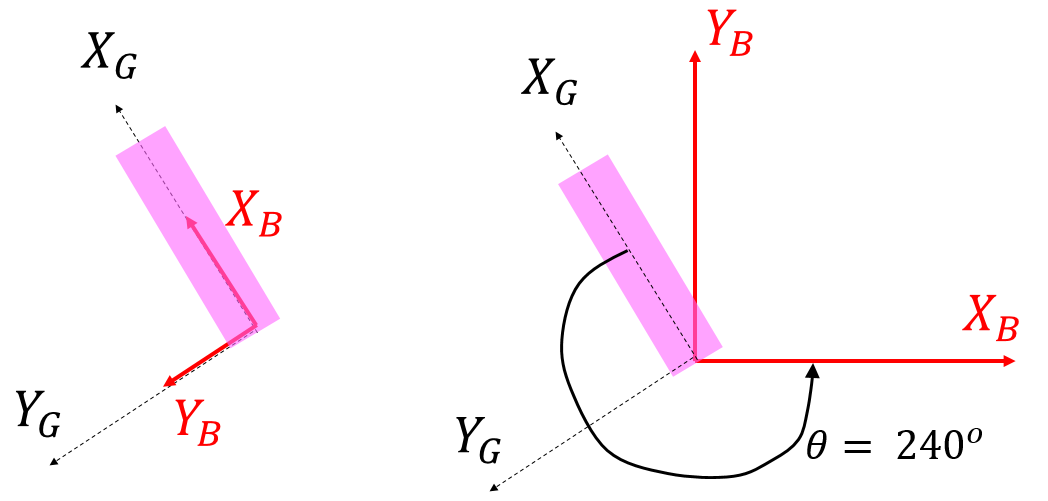

In the above diagram we have 2 frames: the *G-frame* and the *B-frame*.  Initially both of the frames are co-incident.  We then rotate the *B-frame *by an angle $\theta$ to it's new position. 

What we want to do now, is to calculate the inertia matrix of the PINK blade relative to the new position of the *B-frame *shown in the right hand figure*, ie: *$^BI$.  What we know already is the inertia of the pink blade relative to it's local *G-frame, ie: *$^GI$. 

So how do we do calculate $^BI$?  Well the answer starts with our equations for angular momentum.  C*onsider the following*:


$${^B\omega} = {^BR_G}\,\,.{^G\omega} \qquad \Longrightarrow \qquad {^G\omega} = {^BR_G^T}\,\,.{^B\omega}$$



$${^BL} = {^BR_G} \,\,.{^GL} \qquad \Longrightarrow \qquad {^GL} = {^BR_G^T} \,\,.{^BL}$$


Now let's focus on the angular momentum described in the G-frame


$$^GL = {^GI} \,\,.{^G\omega}$$



$$( {^BR_G^T} \,\,.{^BL}) = {^GI} \,\,.({^BR_G^T} \,\,.{^B\omega})$$



$$^BL = ({^BR_G \,\,.{^GI} \,\,.{^BR_G^T}) \,\,.{^B\omega}$$



$$^BL = {^BI} \,\,.{^B\omega}   \qquad where \qquad {^BI} = ({^BR_G \,\,.{^GI} \,\,.{^BR_G^T}) $$
   

The **BIG result** here is this one:  $\bf {^BI} = ({^BR_G \,\,.{^GI} \,\,.{^BR_G^T}) $ .  At the heart of this derivation is a PASSIVE rotation matrix $^BR_G$.  This rotation matrix allows us to compute the components of a vector in the B-frame, when we already know the components of the same vector in the G-frame, ie:  


$$\vec{^Bv} = {^BR_G} \,\,.\vec{^Gv}$$


"think" that the B-frame has rotated relative to the G-frame, ie:

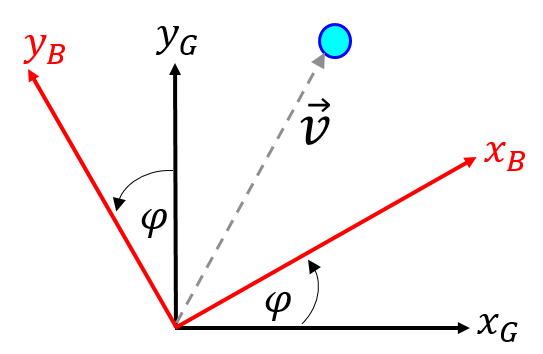

## Now let's consider the PINK blade:

As discussed in the previous section, we have a *G-frame* and a *B-frame*.  Initially the B and G frames are coincident. The B-frame is then rotated by an angle $\theta$ around the Z-axis as shown in the figure below.  In our case we have $\theta = 240^o$ (the angle is positive because of our right hand rule)

% create a PASSIVE rotation object
syms theta
pasR_OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, [ theta ], 'SYM');

% extract the PASIVE rotation matrix bRg
bRg = pasR_OBJ.get_R1

$$bRg = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% In our case we have theta = 240 degrees (== 240 * (pi/180) radians)
bRg = subs(bRg, theta, 240*pi/180)

$$bRg = \left(\begin{array}{ccc} -\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

% now compute bI for the PINK blade
gI            = I_LOCAL_blade;
I_PINK_blade  = bRg * gI * bRg.'

$$I\_PINK\_blade = \left(\begin{array}{ccc} \frac{m\,{\mathrm{Lx}}^{2}}{4}+\frac{m\,{\mathrm{Ly}}^{2}}{48} & \frac{\sqrt{3}\,{\mathrm{Lx}}^{2}\,m}{12}-\frac{\sqrt{3}\,{\mathrm{Ly}}^{2}\,m}{48} & 0\\ \frac{\sqrt{3}\,{\mathrm{Lx}}^{2}\,m}{12}-\frac{\sqrt{3}\,{\mathrm{Ly}}^{2}\,m}{48} & \frac{m\,{\mathrm{Lx}}^{2}}{12}+\frac{m\,{\mathrm{Ly}}^{2}}{16} & 0\\ 0 & 0 & \frac{{\mathrm{Lx}}^{2}\,m}{4}+\frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)$$

## Now let's consider the GREEN blade:

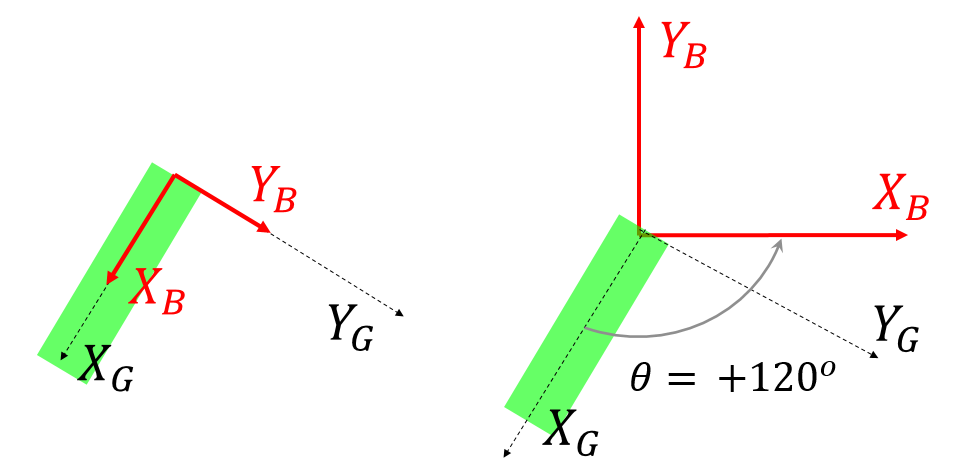

To calculate the inertia of the GREEN blade relative to the new B-frame, we apply the same analysis as we did with the pink blade.

% extract the PASIVE rotation matrix bRg
bRg = pasR_OBJ.get_R1

$$bRg = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% In our case we have theta = 120 degrees (== 120*pi/180 radians)
bRg = subs(bRg, theta, 120*pi/180)

$$bRg = \left(\begin{array}{ccc} -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ -\frac{\sqrt{3}}{2} & -\frac{1}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

% % now compute bI for the GREEN blade
gI             = I_LOCAL_blade;
I_GREEN_blade  = bRg * gI * bRg.'

$$I\_GREEN\_blade = \left(\begin{array}{ccc} \frac{m\,{\mathrm{Lx}}^{2}}{4}+\frac{m\,{\mathrm{Ly}}^{2}}{48} & \frac{\sqrt{3}\,{\mathrm{Ly}}^{2}\,m}{48}-\frac{\sqrt{3}\,{\mathrm{Lx}}^{2}\,m}{12} & 0\\ \frac{\sqrt{3}\,{\mathrm{Ly}}^{2}\,m}{48}-\frac{\sqrt{3}\,{\mathrm{Lx}}^{2}\,m}{12} & \frac{m\,{\mathrm{Lx}}^{2}}{12}+\frac{m\,{\mathrm{Ly}}^{2}}{16} & 0\\ 0 & 0 & \frac{{\mathrm{Lx}}^{2}\,m}{4}+\frac{m\,\left({\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{12} \end{array}\right)$$

## Now assemble the inertias of all three blades:

I_sys_config_1 = I_BLUE_blade + I_PINK_blade + I_GREEN_blade;
simplify(I_sys_config_1)

$$ans = \left(\begin{array}{ccc} \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{8} & 0 & 0\\ 0 & \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{8} & 0\\ 0 & 0 & \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{4} \end{array}\right)$$

Note from the above system INERTIA matrix that our product of inertia terms (eg: ${I_{XY}} \enspace , {I_{YZ}} \enspace , etc$) are all ZERO.  And note also that the $I_{XX}$ and $I_{YY}$moment of inertia terms are identical.  **This is cool !**  .... But is it "lucky" cool or is there something deeper here that we need to explore ?

## Consider an arbitrarily orientated propeller:

Consider the following arbitrarily orientated propeller system:

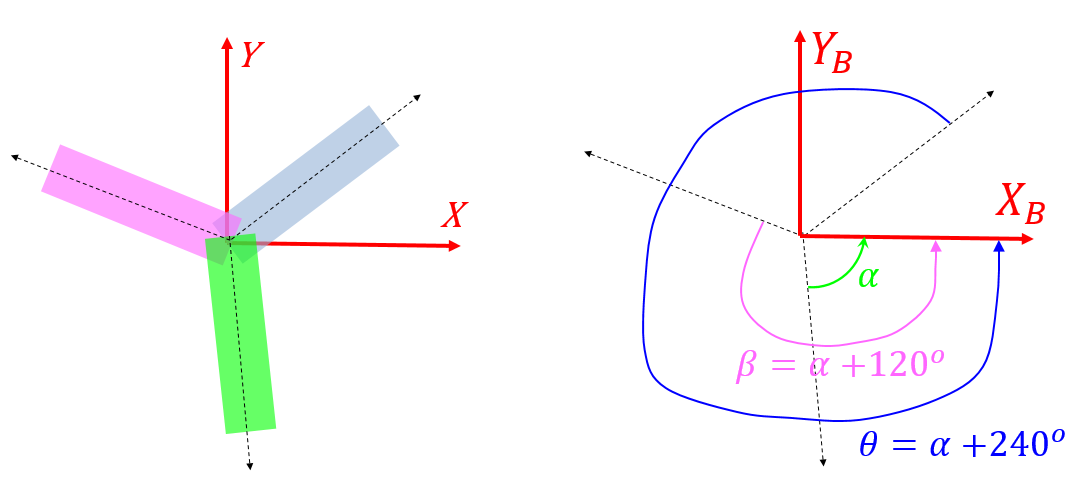

% create a PASSIVE rotation object
syms alpha
GREEN_OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, [   alpha ],              'SYM');
PINK_OBJ  = bh_rot_passive_G2B_CLS({'D1Z'}, [ (alpha + 120*pi/180) ], 'SYM');
BLUE_OBJ  = bh_rot_passive_G2B_CLS({'D1Z'}, [ (alpha + 240*pi/180) ], 'SYM');

% Have a look at each of the PASSIVE rotation matrices bRg
GREEN_bRg = GREEN_OBJ.get_R1

$$GREEN\_bRg = \left(\begin{array}{ccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

PINK_bRg  = PINK_OBJ.get_R1

$$PINK\_bRg = \left(\begin{array}{ccc} \cos\left(\alpha +\frac{2\,\pi }{3}\right) & \sin\left(\alpha +\frac{2\,\pi }{3}\right) & 0\\ -\sin\left(\alpha +\frac{2\,\pi }{3}\right) & \cos\left(\alpha +\frac{2\,\pi }{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

BLUE_bRg  = BLUE_OBJ.get_R1

$$BLUE\_bRg = \left(\begin{array}{ccc} \cos\left(\alpha +\frac{4\,\pi }{3}\right) & \sin\left(\alpha +\frac{4\,\pi }{3}\right) & 0\\ -\sin\left(\alpha +\frac{4\,\pi }{3}\right) & \cos\left(\alpha +\frac{4\,\pi }{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% define a function for computing the XY frame inertia for each blade
I_fh = @(bRg, Ig)(bRg * Ig * bRg.');

% calculate the inertias relative to the X,Y frame
gI            = I_LOCAL_blade;
I_GREEN_blade = I_fh(GREEN_bRg,  gI);
I_PINK_blade  = I_fh( PINK_bRg,  gI);
I_BLUE_blade  = I_fh( BLUE_bRg,  gI);

% combine for the SYSTEM inertia matrix
I_sys_config_arb = I_GREEN_blade + I_PINK_blade + I_BLUE_blade;
simplify(I_sys_config_arb)

$$ans = \left(\begin{array}{ccc} \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{8} & 0 & 0\\ 0 & \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{8} & 0\\ 0 & 0 & \frac{m\,\left(4\,{\mathrm{Lx}}^{2}+{\mathrm{Ly}}^{2}\right)}{4} \end{array}\right)$$

Note from the above system INERTIA matrix, that even when the propeller is placed in an arbitrary pose, the product of inertia terms (eg: ${I_{XY}} \enspace , {I_{YZ}} \enspace , etc$) are still all ZERO and our 2 moment of inertia terms $I_{XX}$ and $I_{YY}$ are still identical (ie: ${I_{XX}} ={I_{YY}}$). Note also that the pose angle $\alpha$does NOT appear in the Inertia matrix !   - so regardless of the in plane orientation of the propeller, the INERTIA matrix is always the same !

So? - So the 3 bladed propeller has INERTIA properties that are ***similar*** to a thin circular disc. 

**This is truly an amazing result !**

*FYI: Here are the inertia values fro a circular disk (see* [***REF***](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)*)*